# **1. Overview**

**How to use this tutorial:** This live matlab script is part of the Spike train Similarity Space (SSIMS) and Similarty Network (SIMNETS) neural analysis tool-box. It's purpose is to provide the user with a 'how-to-guide' in running the main SIMNETS function (`SSIMNETS.m`) and to the illustrate the various operations performed by its sub-functions. Certain features of this tutorial will work best with Matlab Version >= R2018.  When analyzing your own data, we reccommend using the** '**`SSIMNETS.m'` function (rather than this Live Tutorial Script) for increased speed. This following sections of this tutorial will cover: 1) SIMNETS Inputs, 2) Running SIMNETS, 3) SIMNETS Outputs, and 4) looking under-the-hood of SIMNETS. 

**Getting Started:** This code requires the 'SSIMS & SIMNETS toolbox' + the helper functions. The toolbox is completely implemented in MATLAB. To get started, just add the sub-folders ``for_MATLAB`` and '`demo`' and '`matlab helpers`' to your MATLAB path. However, as certain basic MATLAB functions are rather slow, the core functionality has *also* been implemented in C/C++ and can be compiled as `mex` files.  The C/C++  optimized version of the tool box will improve performance dramatically (2 orders of magnitude faster). Setting up the compilier environment will take about 10-15 minutes, but this is time saved down-the-line.See` doc\INSTALL.md `for instructions on installing the c++ optimzed version of the toolbox for your specific OS. 

This live script will run the SIMNETS algorithm using one of two possible demo datasets that are provided with this tool-box (uncomment preferred demo dataset in Section 2). 

                                                                  --------------------------------------------------------------------------------------------------

**What is the SIMNETS algorithm?** The SIMNETS algorithm is designed to compute a Neuron (functional) Similarity Map for a population of simultaneously recorded neurons, calculate the optimal number of sub-nets (i.e., neuron clusters) in the map, and then graphically display a 3D visualization of the Neuron Similarity Map containing the sub-nets. Note: this algorithm *does not* require knowledge of the neuron tuning functions (or even that they have any defined tuning functions) or knowledge of the information encoded in on individual trials, i.e., the specific internal or external covariate(s) that the neurons are responding to.

**INPUTS: **Although there are several input paramters for the SIMNETS algorithm, 5 are **required **under this implementation**: **

**Neural Data (2 inputs):** the user can choose betwen one of two possible demo datasets that are provided with this tool-box (uncomment preferred demo dataset in Section 2). If you want to analyze your own neural dataset, you will need: 

- **A list of** **spike timestamps (in seconds) **for each of the simultaneously recorded neurons (N). Ideally, the spike data will be spike-sorted into single-unit. SIMNETS will technically also work with the multi-unit data, however, you should factor this into your interpretation of the 'Neuron' similarity maps. 

- **A list of event timestamps (in seconds)** for each of the events of interest (just start times). The events of interest can coorrespond to stimulus onset times, movement onset times, decision correlates, or even the onset of an interesting neural phenomenon (e.g., seziures activity, lfp gamma oscillation,  a particular phase of theta oscillatory activity). Events could also represent different time epochs within a trial that is composed on multiple stages, e.g., movement planning and execution. The events timestamps could also correspond to arbritrary events, e.g., every 1 second of a 30 minute period of sleep data, for example.  

**Parameters (4 inputs):** The user should vary these *required* parameters and other optional *parameters* to get a intuition for how their settings can effect the structure of the SIMNETS Neuronal Similarity Map and how their manipulation can faciliate hypothesis testing. Some of the parameters that will have the biggest impact on the Neuron Similarity maps include:                          

- **Win_len (in seconds):** Spike train window length (in seconds)

- **start_offset (in seconds):** Start of spike trains relative to the event of interest (e.g., 0.1 seconds before the start of movement event). 

- *** q ***: Temporal sensitivity of spike train comparison. Part of a cost-based edit-distance function [4] used to estimate similarity between spike trains that determine   the cost of 'shifting' a spike in time relative to insterting/deleting spikes. Low *q* values (e.g., *q* = 0) only register firing rate differences between the two spike trains being compared, whereas higher q values register differences in spike positions across the two spike trains being compared with increasing precision (e.g.,  q:100 = 10ms).

- **Perplexity: **number of neurons used to define a 'local neighbour' in the neuron space during dimensionality reduction with tSNE [5].  The goal of tSNE is to preserve the local neighbourhood structure found in the high-dimensional space when projecting to lower-dimesions.

                                                             --------------------------------------------------------------------------------------------------

**Cite: **please cite the DOI for the SIMNETS paper and the DOI for the Software Repository (doi: xxxx) when using this software and/or this analysis framework for analyzing your own data. 

 [1] SSIMS and SIMNETS toolbox: DOI**:** [https://doi.org/](https://doi.org/)  

[2] Jacqueline Hynes, David Brandman,  Jonas Zimmerman, John Donoghue, Carlos Vargas-Irwin (2018). "[**SIMNETS: a computationally efficient and            scalable framework for identifying networks of functionally similar neurons**](https://www.biorxiv.org/content/early/2018/11/09/463364)" . **DOI:** [https://doi.org/10.1101/463364)](https://doi.org/10.1101/463364))       

[3] Vargas-Irwin, C. E., Brandman, D. M., Zimmermann, J. B., Donoghue, J. P., & Black, M. J. (2015). [** "Spike Train SIMilarity Space (SSIMS): A Framework for Single Neuron and Ensemble Data Analysis (2014).**](https://www.ncbi.nlm.nih.gov/pubmed/25380335)**"**

**[4 ] **Victor, Jonathan D. “**Spike train metrics**” *Current opinion in neurobiology* vol. 15,5 (2005): 585-92.

**[5] **.J.P. van der Maaten and G.E. Hinton. **Visualizing High-Dimensional Data Using t-SNE**. *Journal of Machine Learning Research* 9(Nov):2579-2605, 2008.

@author Jacqueline Hynes. Copyright (c) Jacqueline Hynes, Brown University. All rights reserved.

Questions? Contact <Carlos Vargas_irwin@brown.edu>  or <Jacqueline Hynes@Brown.edu>. We are happy to help with any trouble shooting or provide guidance on how to best analyze your own data.

# **2. INPUTS -  Neural data & Parameters**    

## **Load Data:**

- Dataset 1 (simulated ensembles with mixed coding schemes): simulated spike train data from a population N = 180 synthetic neurons with diverse coding schemes (dataset 1 from SIMNETS paper [1]). The population consist of three functionally distinct neuron sub-groups (N = 60, neurons per ensemble). Neurons in a common ensemble have similar response properties but diverse coding properties. In other words, neurons from a common ensemble encode the same information using a different coding format. Each ensemble contains three different neuron sub-type:)) rate coding neurons (N = 20, neurons per ensemble), temporal coding neurons  (n = 20, neurons per ensemble), and rate+temporal coding neurons (n = 20, neurons per ensemble).  SIMNETS is expected to cluster the neurons in this dataset according to their functional properties when the temporal resolution of the analysis is such that the algorithm is senstive to the information encoded in both spike rates and spike times, i.e. when the temporal accuracy paramater *q*>0. See [2] for more details.              

                %load('SIMNETS_simulatedData_mixedCodingFormat.mat');       % SIMULATED DATA

- Dataset 2 (real M1 neuron population): This data comes from a population of real primate M1 neurons whose spiking activity was recorded using a 96-channel electrode array during a center-out reaching task ( 8 reach directions). Although SIMNETS  doest not requires knowledge of the neuron's tuning functions, we estimated the neuron's preferred-reach direction so that we can later validate the results of the SIMNETS algorithm. See [2] for more details. 

                load('SIMNETS_realData_centerOutM1.mat')                  % REAL M1 DATA (Uncomment to load)

## **Set Inputs: **

- **spiketrains**: Cell array with spike train data from a population of neurons. Spike trains are double arrays whose entries correspond to times of spike occurences, in seconds, referenced to a common zero. 

        spiketrains        % Spike timestamps

spiketrains = 1×103 cell array
    {11077×1 double}    {43816×1 double}    {10921×1 double}    {42483×1 double}    {7260×1 double}    {2323×1 double}    {18296×1 double}    {31709×1 double}    {110220×1 double}    {7429×1 double}    {31283×1 double}    {32771×1 double}    {7506×1 double}    {3830×1 double}    {2069×1 double}    {17671×1 double}    {89579×1 double}    {18239×1 double}    {24136×1 double}    {36386×1 double}    {28527×1 double}    {21703×1 double}    {70297×1 double}    {56549×1 double}    {44857×1 double}    {86258×1 double}    {16120×1 double}    {12256×1 double}    {55762×1 double}    {105568×1 double}    {23662×1 double}    {16135×1 double}    {126546×1 double}    {5700×1 double}    {8379×1 double}    {49496×1 double}    {4372×1 double}    {11913×1 double}    {67569×1 double}    {22301×1 double}    {25465×1 double}    {10291×1 double}    {46529×1 double}    {9870×1 double}    {2586×1 double}    {8012×1 double}    {18220×1 double}    {7189×1 double}    {35412×1 double

- **events:** event times (in Sec), in seconds, referenced to the same common zero as spikes.          

        events;             % Spike train window duration     

- **spiketrain window** ( in seconds), and the leading edges of the analysis window relative to event times. Note: the temporal accuracy (1/q) should never be larger than the window length. 

        win_len = 1         % Spike train window duration

win_len = 1

  
        start_offset = 0    % Spike train window offset 

start_offset = 0

- **Temporal accuracy** parameter (from Victor & Purpura). When timeing in Sec,  1/q = temporal sensitivity: q = 0 ( rate), q = 10 (100 msec), q = 200 (5 ms).  

        q = 30            % Temporal Accuracy

q = 30

- **Perplexity value** (specific to tSNE algorithm): # of neurons that influence a given neuron during dimensionality reduction  

        perplexity = 30   % Number of effective nearest neighbours (neurons) during 

perplexity = 30

                                                   % tSNE dimensionality reduction                                        

- **Number of dimensions (optional)** for k-means clustering and visualization of Neuron Relational Map. Note: a PCA variance analysis may be used to determine the max number of dimensions in which the clustering should be performed. Neuron similarity map can be vizualized in 2 or 3 dimensions.    

     displaydim = 2     % Dimensionality of the visualization space. Default = 3. 

displaydim = 2


     clusterdim =5    % Estimation of the instrinsic dimensionality of the neuron 

clusterdim = 5

                                               % space i.e., how many dimensions can capture the relationships
                                               % between neurons. Default = 10.  

- **Range of neuron clusters (optional)** to test for: Larger neuron population numbers will potentially contain more neuron clusters. Default: 10

     crange = 10                               % Max cluster number to search for in Neuron sapce. Default = 10.

crange = 10

- **Dimensionality Reduction type (optional)**: Larger neuron population numbers will potentially contain more neuron clusters. Please 

     drTechnique = 'tsne'                     % tsne, MDS, or PCA. Default = 'tsne'.

drTechnique = 'tsne'

- **Shuffle Iterations - test significance of detected clusters (optional):**  

     iterations = 0            % Turn off shuffle-based statistical test (default = 0) or select a specific

iterations = 0

                                                 %  number of iterations (e.g., 100)
 

Constants/pre-allocations: 

 spktNum = numel(events);   % number of spike trains (i.e., stimulus events/trials)
 nn = length(spiketrains);  % number of neurons
 NSmat = zeros(nn,nn);      % pre-allocate NxN Neuron Similarity Matrix


# 3. Running SIMNETS

**Run: **Run the main SIMNETS function and plot the outputs:

[  SNETS   ]  =   SSIMNETS( spiketrains , events , win_len , q , perplexity,...
     'displaydim', displaydim, 'clusterdim', clusterdim, 'crange', crange, 'iterations',iterations); 

Mean value of sigma: 0.082341
Minimum value of sigma: 0.050889
Maximum value of sigma: 0.14196


**Plotting:** 

**a) Neuron Similarity Map (with neuron type labels)**  

subplot(1, 2, 1); 
plotNT(SNETS.NSmap,nTypes,'color', colorMatrix); 
title('Neuron Similarity Map with neuron type labels)', 'fontsize' , 12); 

    if nn==180
       legend(nTypeLabels,'location',  'bestoutside')
    end     

**b) Neuron Similarity Map (with sub-net assignment labels)  **

subplot(1, 2, 2); 
plotNT(SNETS.NSmap,SNETS.clusterindex); 
set(gcf, 'position',[  184  410   1117     460]) 
title('Neuron Similarity Map with k-means cluster labels)' , 'fontsize' , 12); 
legend(cluLabels,'location',  'bestoutside'); 

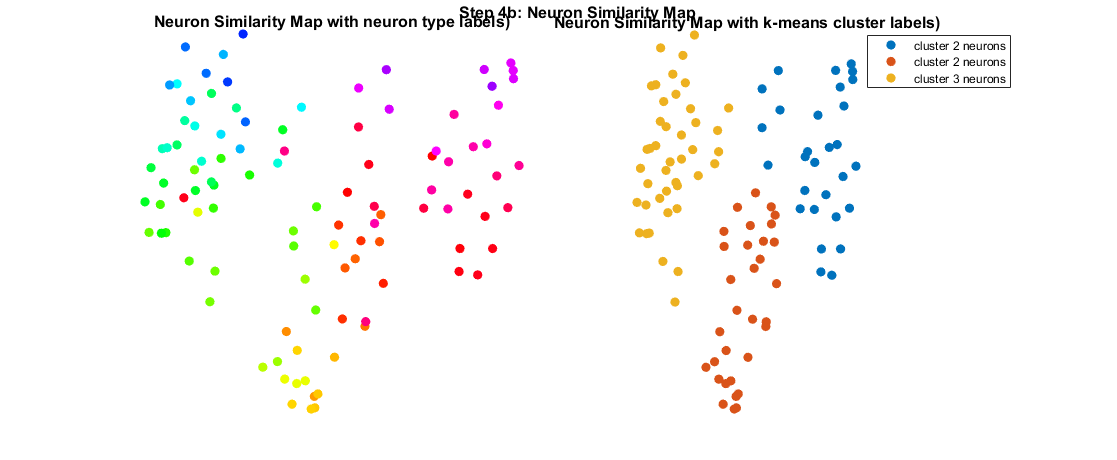

supertitle('Step 4b: Neuron Similarity Map\newline ', 'fontsize',12);

# 4. Under-the-hood of SIMNETS 

**Step 1)** Within-neuron spike train (S) comparisons: use a spike train metric (distance measure) to generate a SxS Spike Train Similarity (SSIM)  matrix for each neuron.   

**Step 2)** Between-neuron comparisons: calculate correlation between each pair of single neuron SSIMS matrices to generate an NxN Neuron Similarity (Correlation) Matrix.

**Step 3)** Generate a low-dimensional neuron similarity map: map neuron similarity measures from the high-dimensional neuron space to a low-dimensional neuron space using t-SNE. 

**Step 4)** Cluster detection and vizualization: Determine if there are a statistically signifant number of neuron groupings (*k*) in the data; plot low-dimensional neuron map

## 1) Generate a SxS Spike Train Similarity Matrix (SSIM) for each neuron:

This function calculates the Victor-Purpura spike train distances for all pairs of spike trains for each neuron ( i.e,  'within-neuron' spike train distances). A .mex and .m version of the `getSSIMDMatBetweenTimePoints.m` function is included in the SIMNETS tool-box 

- **Inputs:** cell array with spike train data; event times; window duration (s); temporal accuracy parameter, q.

- **Outputs:** N concatenated SxS Spike train distance matrices (see Figure 1)

[SSIMmats, basespiketrains] = getSSIMDMatBetweenTimePoints(spiketrains, events+start_offset, win_len, q);

 

**Plotting:**

**Example SSIM matrices for four neurons  **

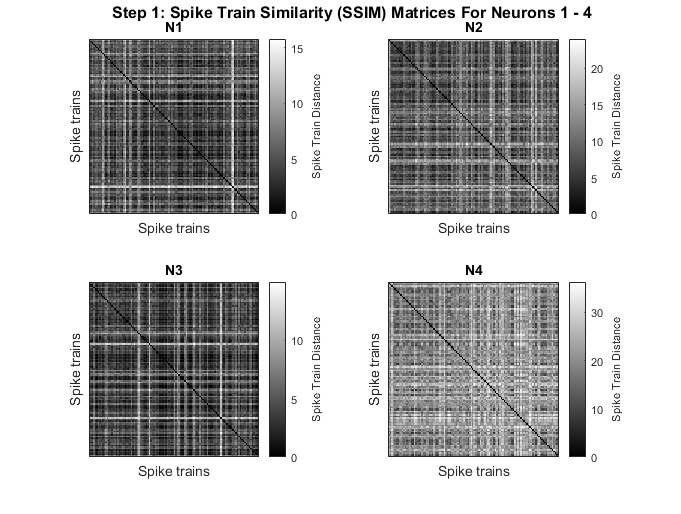

figure
    for x = 1:4
          
        subplot(2,2,x);
        imagesc(SSIMmats(1:spktNum,(1:spktNum)+((x-1)*spktNum)));
           
        h1 = colorbar; colormap gray   
        ylabel(h1, 'Spike Train Distance');title(['N' num2str(x)]); 
        set(gca,'XTick',[], 'YTick', []); xlabel('Spike trains'); ylabel('Spike trains')     
    end       
    supertitle('Step 1: Spike Train Similarity (SSIM) Matrices For Neurons 1 - 4\newline ', 'fontsize',12); 
    set(gcf, 'position',[680   270   681   514]);

## 2) Generate a single NxN Neuron Similarity (NS) Matrix 

This loop calculates the pairwise SSIM matrix correlations for all pairs of neurons (i.e., the covariances of the intrinsic spike train distances for each neuron pair).  The output of this stage is an NxN Neuron Similarity Matrix, where each coloumn (or row) captures the functional similarity of a given neuron and all other neurons as an N-dimensional vector of correlation values (See Fig. 2) .  A .m version of this function is included in the SIMNETS tool-box: `SSIMSNeuronRelCorr.m `

 ix1  = 1:spktNum;
  
 for n1 = 1:nn
        
     A = SSIMmats(:,ix1); % Neuron A SSIM matrix
        
     ix2  = 1:spktNum;
        
     for n2 = 1:n1
    
         B = SSIMmats(:,ix2);  % Neuron A SSIM matrix
           
       % Calculate correlation between Neuron A and Neuron B's intrinsic spike train distances 
         NSmat(n1,n2) = corr(A(:),B(:) , 'type', 'pearson');   
               
       % If the SSIM matrix of either neuron is empty, the correlation step will reults in a
       % NaN entry to NSmat, so we replace any NaNs as follows: if both Neuron A and Neuron B
       % do not fire, we set the similarity values to 1 (i.e., the neurons are functionally similar)
       % If either Neuron A or Neuron B is exclusively silent, set similarity value to 0 (i.e., the 
       % neurons are functionally dissimilar). Another conditional statement could be added so that a neuron
       % that fires only 1 spike and a neuron that fires zero spikes are labeled as functionally similar. 
       % This can be achieved by ana examination of the neurons' average spike train distances values, i.e.
       % SSIM matrices that have are zero and near zero spike train distance ==1;  
       
         if all(A(:) == 0) && all(B(:)== 0)   % If either Neuron 'failed' to fire, set Corr(A,B)to 0   
           
             ncmat(n1,n2) = 1;      

          elseif xor([sum(A(:))],[sum(B(:))])

              ncmat(n1,n2) = 0;        % If BOTH Neuron A or Neuron B 'failed' to fire, set Corr(A,B)to 1 (i.e., they were both silent)
     
         end 
        
              
         ix2 = ix2+spktNum; 
            
     end
    
        ix1 = ix1+spktNum;
                   
 end 

 NSmat = tril(NSmat)+tril(NSmat,-1)';  % Copy lower half of matrix to upper half to make symetrical. Diagonal should be filled with ones.  
  

     **Plotting for Step 2: ****NxN Neuron Similarity Matrix** 

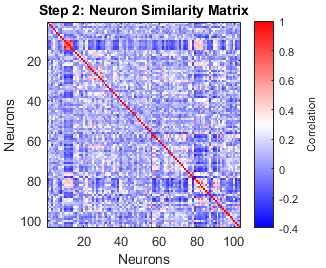

     figure; imagesc(NSmat);
     h = colorbar;
     colormap redblue
     ylabel(h, 'Correlation');
     xlabel('Neurons')
     ylabel('Neurons')
     title('Step 2: Neuron Similarity Matrix')
     set(gcf, 'position',[680   482   326   268])

## 3) Perform Dimensionality Reduction on NxN Neuron Similarity Matrix

Use a dimensionality reduction algorithm, such as tSNE, to reduce the N neuron similarity correlation vectors to a lower dimensional space for the clustering step (e.g., 5-10 dimensions). The 'tsne_PCA' function performs PCA before tSNE to ensure a stable output.  The top three dimensions are selected using PCA for the visualization step (step 4).   

- **Inputs:** Neuron Similarity Map;  number of dimensions for the clustering step; perplexity value 

- **Outputs:** low-dimensional represenation of the NxN Neuron Similarity Map (See Fig. 3) 

    NSmapHD = runtSNE( NSmat,clusterdim,perplexity); 

Mean value of sigma: 0.22771
Minimum value of sigma: 0.14073
Maximum value of sigma: 0.39257


    
    NS_PC  = pca(NSmapHD);                     % Perform PCA on the lower-dimensional t-SNE output structure
    NSmap = NSmapHD*NS_PC(:,1:displaydim);     % Select top 2/3 dimensions for plotting. 
     

 **P****lotting 3:**** t-SNE reduced Neuron Similarity matrix  **

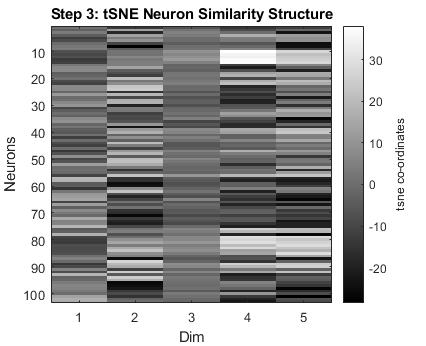

     figure
     imagesc(NSmapHD)
     colormap gray 
     set(gcf, 'position',[680   468  426  346]);
     h = colorbar;
     colormap gray
     ylabel(h, 'tsne co-ordinates');
     ylabel('Neurons')
     xlabel('Dim')
     title('Step 3: tSNE Neuron Similarity Structure');

## 4a)  Cluster Detection: silhouette analysis,  k-means clustering, significance testing

Use k-means clustering tool to cluster neurons in to 'k' cluster, where an optimal k value is calculated using a silhouette analysis. The larger the avg. silhouette value for a given value of k, the better the cluster solution.    

**Silhouette test: **

    [ silhouette, clusterindex, nclus  ] = autokmeanscluster( crange  , NSmap );
   
    [sMax, kIndex] =    max(silhouette);
    

**Silhouette value significance test: **

This step is skipped is  `iterations = 0. `

   
   [ ncmatShift, shufMU, shufCI] = SSIMSNeuronRelCorr_shuffleTest( SSIMmats, iterations, perplexity );  


**Pl****otting 4: Silhouette Plot**

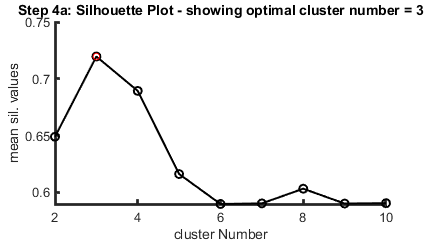

    figure
    jbfill(2:max(crange) ,shufCI(2,2:end) ,shufCI(1,2:end) ,2:max(crange));
    plot(2:max(crange),shufMU(2:end),'r-', 'linewidth',1.5);hold on; 
    plot(2:max(crange), silhouette(2:max(crange)),'ko-', 'linewidth',1.5);hold on; 
    plot(kIndex, sMax,'ro', 'markersize',5);
     
    box off
    hold on; 
    xlabel('cluster Number')
    ylabel('mean sil. values')   
    xlim([ 2 max(crange)])
    set(gcf, 'position',[ 680   855   426   243]);
    set(gca,'linewidth',2)
    title([ 'Step 4a: Silhouette Plot - showing optimal cluster number = ' num2str(kIndex) ])